# DISPOSITIVO 2

- Ricezione del messaggio inviato da dispositivo 1

- Classificazione della comunicazione e cambio di code rate e modulation order

- Invio dei nuovi parametri di trasmissione

- Se viene ricevuto un keep alive, invia gli ultimi  inviati.

[OFDMParams,dataParams, GeneralParam] = helperSetParameters();
endureCommunication = 1;

### RICEZIONE

Attesa di ricezione


## Establishing connection to hardware. This process can take several seconds.



BER = 0 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 


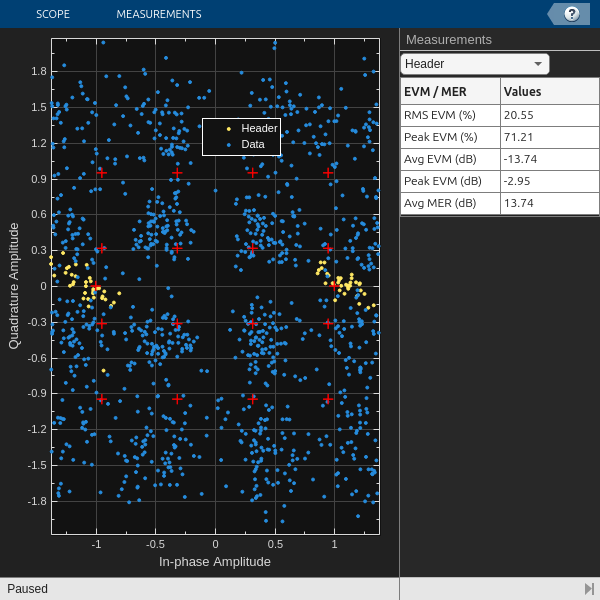

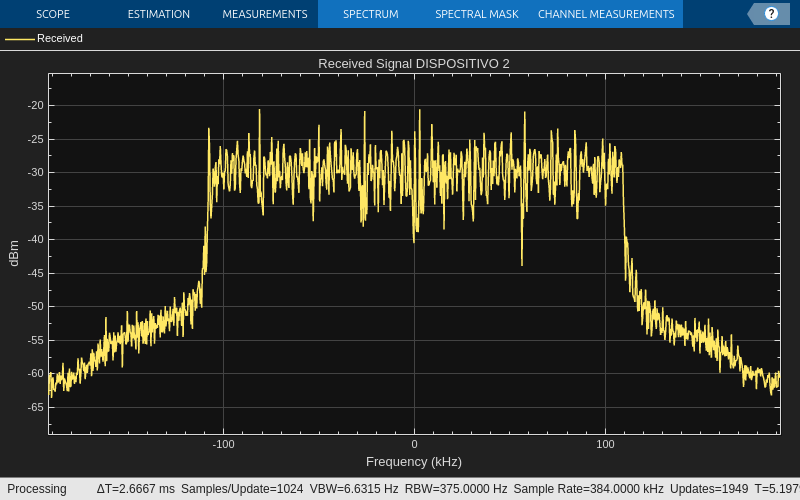

while endureCommunication
    fprintf('Attesa di ricezione\n');
    [rxFlag, params] = helperReceiverModule(GeneralParam, OFDMParams, dataParams);
    if ~rxFlag
        endureCommunication = 0;
    else
        fprintf('Passo in trasmissione\n');
        GeneralParam.message = params;
        GeneralParam.carrier_frequency = GeneralParam.carrier_frequency - 0.001;
        helperTrasmissionModule(GeneralParam,OFDMParams, dataParams);
    end
    pause(3);
    GeneralParam.carrier_frequency = GeneralParam.carrier_frequency + 0.001;
end

fprintf('Comunicazione terminata\nNon è stato ricevuto nulla!\n');

Comunicazione terminata
Non è stato ricevuto nulla!
